syms theta1 theta2 theta3 % Déclaration des angles comme symboles

% Longueurs des segments
a1 = 2; % Longueur du segment entre O et A (fixe)
a2 = 3; % Longueur du segment entre A et B
a3 = 2; % Longueur du segment entre B et C

% Positions des articulations
O = [0, 0]; % Position de l'origine
A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)

% Convertir les expressions symboliques en fonctions anonymes Dans MATLAB, 
% les expressions symboliques telles que celles définies pour les positions des articulations 
% ne peuvent pas être directement utilisées avec des valeurs numériques des angles. 
% La fonction matlabFunction est utilisée pour convertir ces expressions symboliques 
% en fonctions anonymes, qui peuvent ensuite être appelées avec des valeurs numériques des angles 
% pour évaluer les positions des articulations.
% Par exemple, pos_A, pos_B et pos_C sont définies comme des fonctions anonymes qui 
% prennent en argument les angles des articulations et renvoient les positions 
% correspondantes des articulations AA, BB et CC. Ces fonctions permettent de 
% traiter les expressions symboliques comme des fonctions numériques.
pos_A = matlabFunction(A);
pos_B = matlabFunction(B);
pos_C = matlabFunction(C);

% Valeurs numériques des angles
theta_values = [0, pi/2, pi/2]; % Exemple d'angles

% Évaluation des positions des articulations pour les angles donné. les valeurs numériques des angles sont stockées dans le vecteur 
% theta_values. En utilisant ces valeurs, nous appelons les fonctions pos_A, pos_B et pos_C 
% pour obtenir les positions numériques des articulations Ces positions numériques sont ensuite utilisées pour 
% tracer le robot dans la fenêtre de visualisation.
A_num = pos_A(theta_values(1));
B_num = pos_B(theta_values(1), theta_values(2));
C_num = pos_C(theta_values(1), theta_values(2), theta_values(3));

% Tracé du robot
plot([O(1), A_num(1)], [O(2), A_num(2)], 'b', 'LineWidth', 2); % Segment OA
hold on;
plot([A_num(1), B_num(1)], [A_num(2), B_num(2)], 'r', 'LineWidth', 2); % Segment AB
plot([B_num(1), C_num(1)], [B_num(2), C_num(2)], 'g', 'LineWidth', 2); % Segment BC
scatter([O(1), A_num(1), B_num(1), C_num(1)], [O(2), A_num(2), B_num(2), C_num(2)], 100, 'filled'); % Marques pour les articulations
xlim([-10, 10]); ylim([-10, 10]); % Définition des limites des axes
axis equal; % Mise à l'échelle des axes
title('Modélisation du robot 2D à 4 articulations');
xlabel('X'); ylabel('Y');
grid on; % Affichage de la grille


disp('Coordonnées de l''effecteur C :');

Coordonnées de l'effecteur C :


disp(C_num);

    0.0000    3.0000



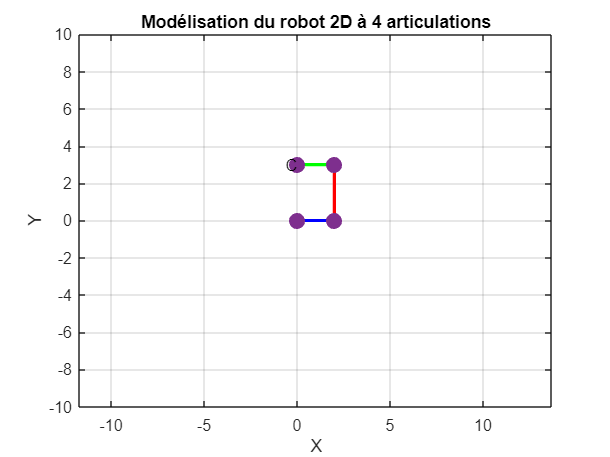

text(C_num(1), C_num(2), 'C', 'HorizontalAlignment', 'right');